t = 1:16000

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


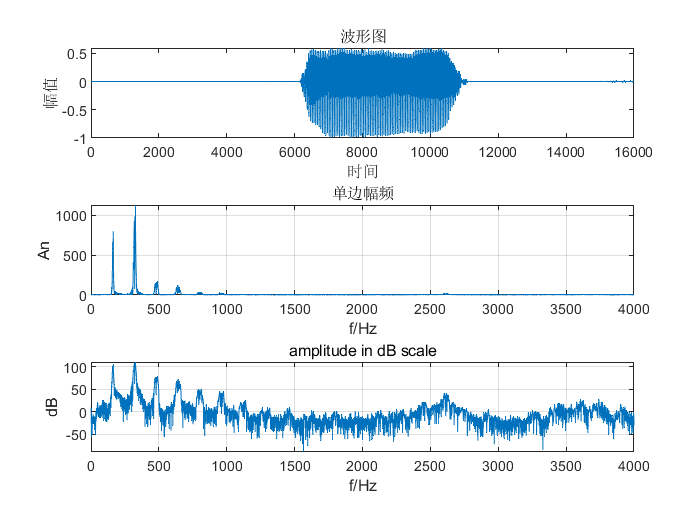

Spectrum(myRecording,t,8000)

function Spectrum(y,t,fs)
    %y为输入信号
    %fs为采样频率
    L = length(y); %信号长度
    Xf = fftshift(abs(fft(y)));
    %快速傅里叶变换，fftshift为去除采样卷积引起的fs/2处重叠。
    subplot(3,1,1);%建立空图形
    plot(t,y)
    title('波形图');
    xlabel('时间');
    ylabel('幅值');
    f = [0:L/2]*fs/L;%横坐标范围[0:fs/2]
    subplot(3,1,2);
    plot(f,Xf(round(L/2):L)*2);%输出单边频谱，取一半乘2。
    title('单边幅频');
    xlabel('f/Hz');
    ylabel('An');
    grid on;%背景网格
    
    Y = 20.*log10(Xf);
    subplot(3,1,3);
    plot(f,Y(round(L/2):L)*2);
    title('amplitude in dB scale');
    xlabel('f/Hz');
    ylabel('dB');
    grid on;
end
